# PART 4: Path planning

close all
clear all
clc 

## 2D  planning Example

### Setup the 2D map

% define map size
max_x = 10;
max_y = 10;
map = zeros(max_x, max_y);

% generate random obstacles
obs_per = 0.3;
for x = 1:max_x
    for y = 1:max_y
        if rand < obs_per
            map(x, y) = 1;
        end
    end
end

% define the starting and end position
start = [1, 1];
end_ = [10, 10];
map(start(1), start(2)) = 0;
map(end_(1), end_(2)) = 0;

### Draw the map

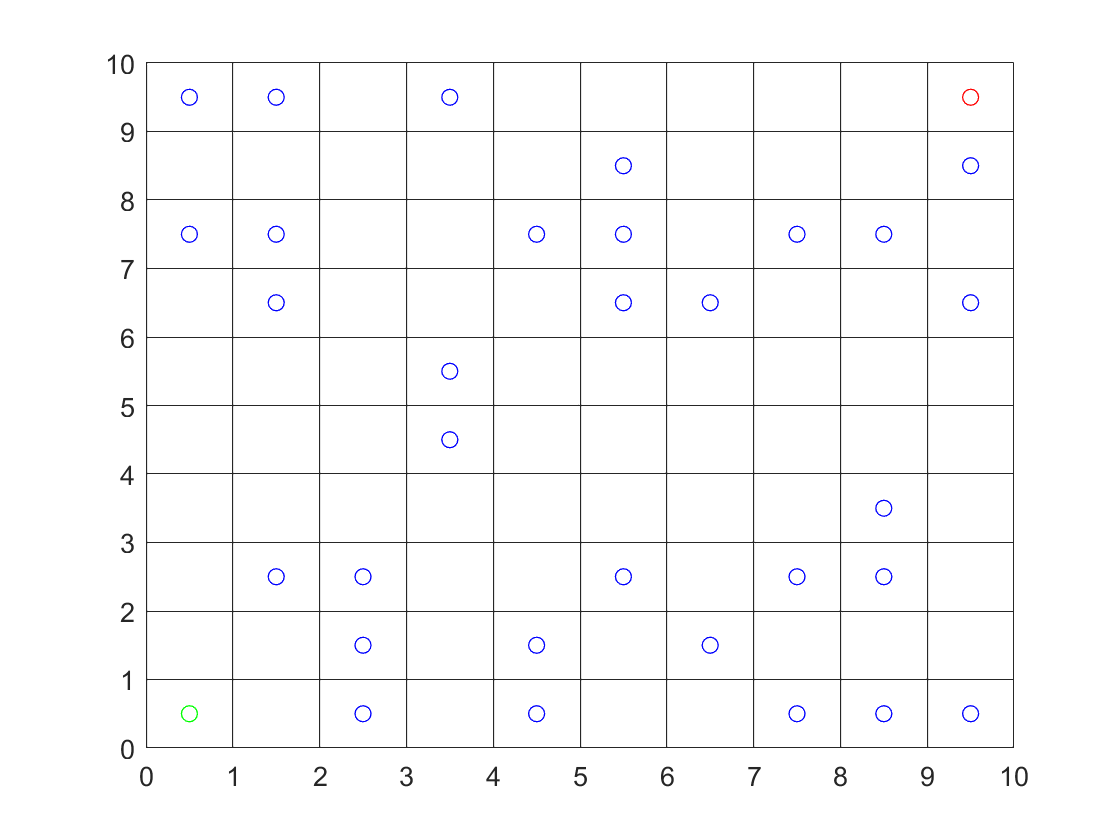

hold off
figure(1)
hold on

% Mark the obstacles with blue
for x = 1:max_x
    for y = 1:max_y
        if map(x, y) == 1
            scatter(x-0.5, y-0.5,[], "blue")
        end
    end
end

% Mark the start with green
scatter(start(1)-0.5, start(2)-0.5, [], "green")
hold on
% Mark the end with red
scatter(end_(1)-0.5, end_(2)-0.5, [], [1, 0, 0])
hold on

%Set the axes
axis([0 max_x 0 max_y])
% Make the grid lines more visible
ax = gca;
ax.GridAlpha = 1.0;
grid on
set(gca, 'xtick', [0:1:max_x])
set(gca, 'ytick', [0:1:max_y])
set(gcf,'Visible','on')

### Running Greedy best-first search

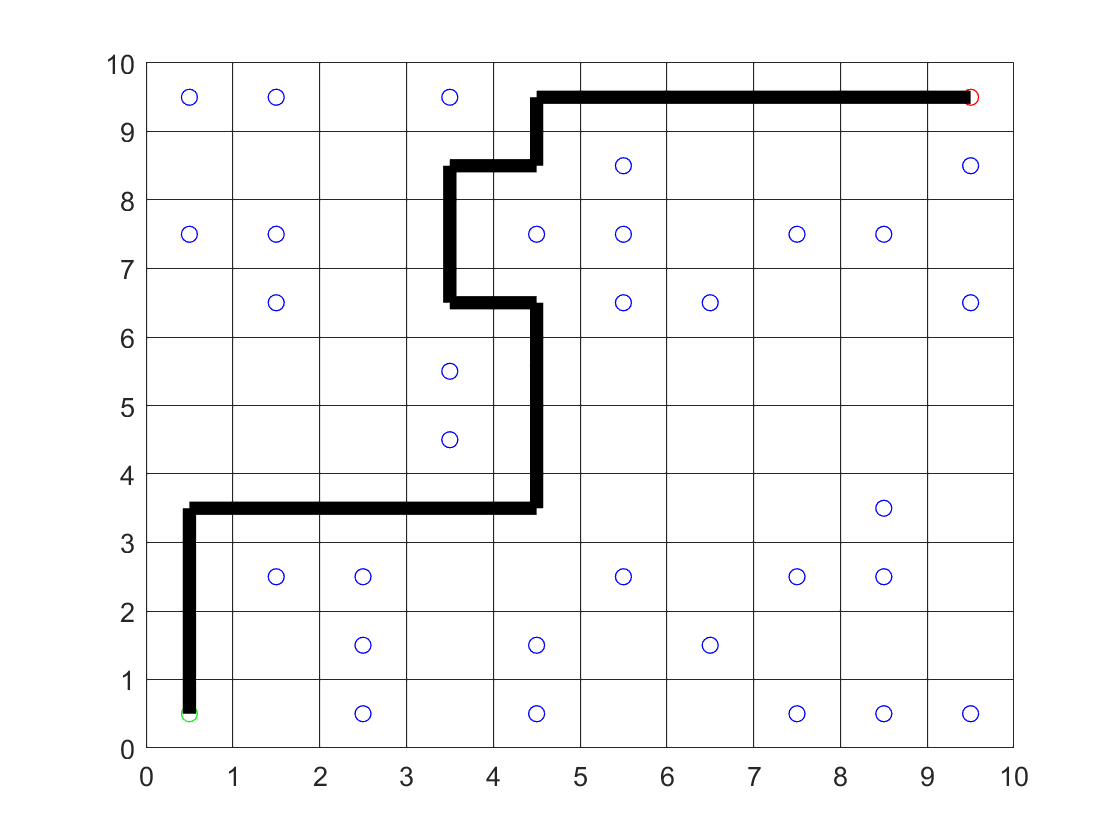

% Run the algorithm to obtain the route
route = greedy2D(map, start, end_); % greedy_2d

% Draw the route
pause on
% route = [x1, y1;
%          x2, y2; ...]
for i = 2:length(route)
    plot([route(i-1, 1)-0.5, route(i, 1)-0.5], ...
         [route(i-1, 2)-0.5, route(i, 2)-0.5], ...
         'Color',[0,0,0], 'LineWidth',5)
    hold on
    pause(0.1)
%     route(i,:);
end

set(gcf,'Visible','on')

## Exercise 4.7: Upgrade the Greedy best-first search from 2D to 3D

close all
clear all
clc

### Setup the 3D map

% Load the map from the wall file. Each line, except the two last, in the
% wall file is an obstacle. The position of the obstacle is defined in the
% wall file by its x y z coordinates. The three last elements is
% the size of the maze, the starting position and goal position
load('wall.txt')
wall = wall;

% define the map size
max_x = max(wall(:,1));
max_y = max(wall(:,2));
max_z = max(wall(:,3));
map = zeros(max_x, max_y, max_z);

% Inpute the obstacles into the map
for i = 1:(length(wall) - 3)
    map = gen_square3d([wall(i, 1) wall(i, 1) + 1;...
                        wall(i, 2) wall(i, 2) + 1;...
                        wall(i, 3) wall(i, 3) + 1], map);
end

% Define the starting and end position
start = wall(length(wall) - 1, :);
end_ = wall(length(wall), :);

% Make sure the start and end is not the obstacle
map(start(1), start(2), start(3)) = 0;
map(end_(1), end_(2), end_(3)) = 0;

### Draw the map

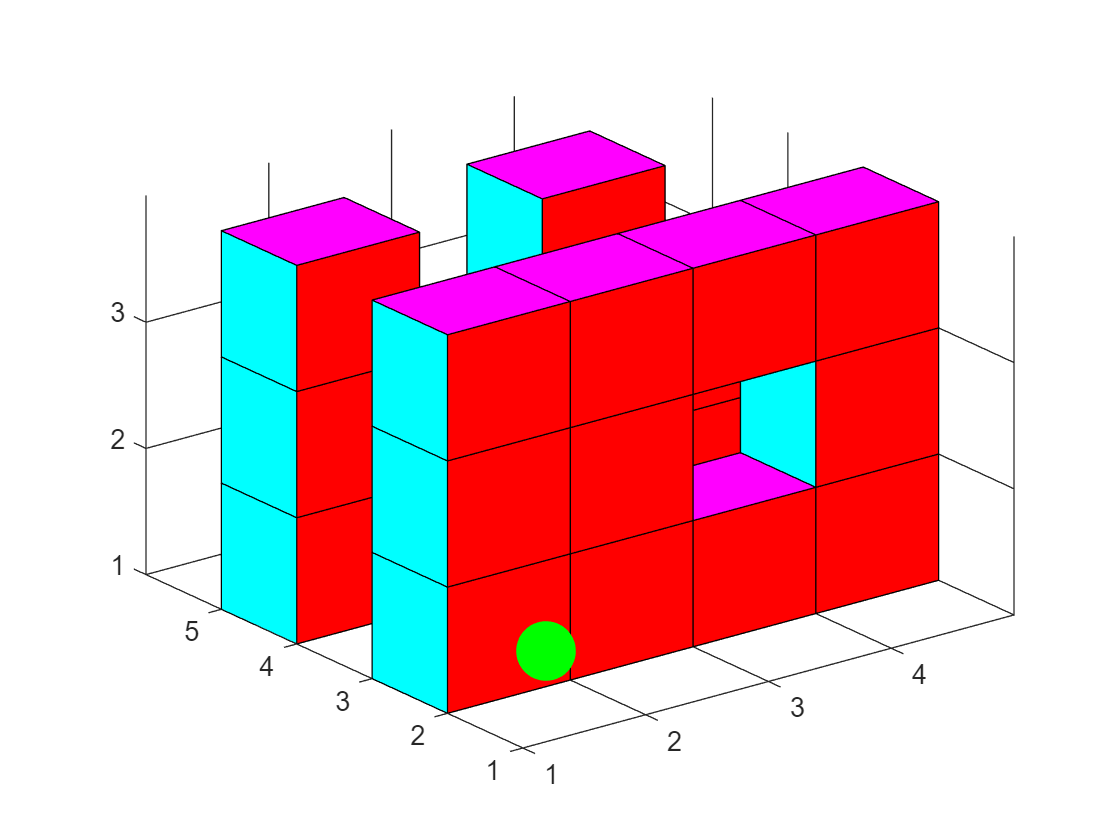

% Draw a figure to show the map and process
hold off
figure(1)
% Mark the start with green
scatter3(start(1)+0.5, start(2)+0.5, start(3)+0.5, ...
         500, [0,1,0],'filled')
hold on
% Mark the end with red
scatter3(end_(1)+0.5, end_(2)+0.5, end_(3)+0.5, ...
         500, [1,0,0], 'filled')
hold on
% Draw the obstacles
for i = 1:(length(wall) - 3)
    map = gen_square3d([wall(i, 1) wall(i, 1) + 1;...
                        wall(i, 2) wall(i, 2) + 1;...
                        wall(i, 3) wall(i, 3) + 1], map, 1);
    
end
% Set the axes
axis([1 max_x+1 1 max_y+1 1 max_z+1])
% Make the grid lines more visible
ax = gca;
ax.GridAlpha = 1.0;
grid on
set(gca, 'xtick', [0:1:max_x])
set(gca, 'ytick', [0:1:max_y])
set(gca, 'ztick', [0:1:max_z])

### Run the algorithm to obtain the route

route = greedy3D(map, start, end_);

### Draw the map and the route

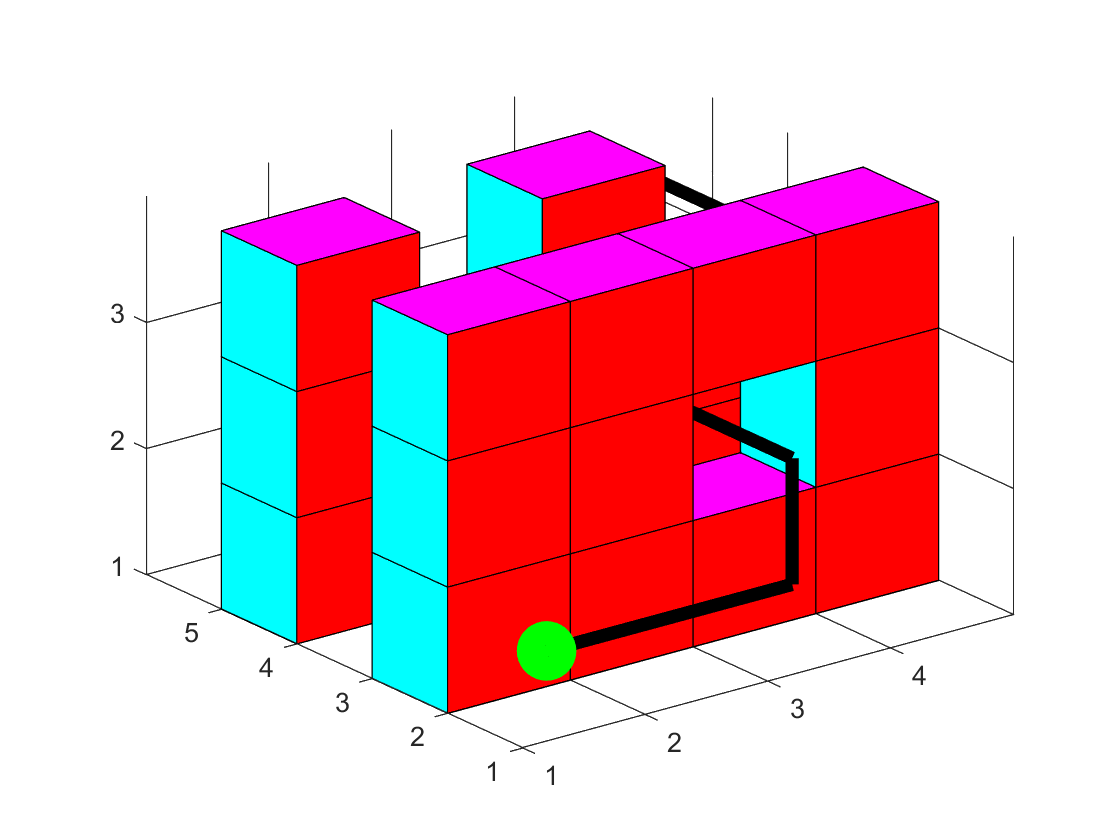

hold off
figure(1)
% Mark the start with green
scatter3(start(1)+0.5, start(2)+0.5, start(3)+0.5, ...
         500, [0,1,0],'filled')
hold on

% Mark the end with red
scatter3(end_(1)+0.5, end_(2)+0.5, end_(3)+0.5, ...
         500, [1,0,0], 'filled')
hold on

% Draw the obstacles
for i = 1:(length(wall) - 3)
    map = gen_square3d([wall(i, 1) wall(i, 1) + 1;...
                        wall(i, 2) wall(i, 2) + 1;...
                        wall(i, 3) wall(i, 3) + 1], map, 1);
    
end

% Set the axes
axis([1 max_x+1 1 max_y+1 1 max_z+1])
% Make the grid lines more visible
ax = gca;
ax.GridAlpha = 1.0;
grid on
set(gca, 'xtick', [0:1:max_x])
set(gca, 'ytick', [0:1:max_y])
set(gca, 'ztick', [0:1:max_z])
pause on;
for i = 2:length(route)
    plot3([route(i-1,1)+0.5,route(i,1)+0.5], ...
          [route(i-1,2)+0.5,route(i,2)+0.5], ...
          [route(i-1,3)+0.5,route(i,3)+0.5], ...
          'color',[0,0,0],'linewidth',5)
    hold on
    pause(0.1)
%     route(i,:)
end
set(gcf,'Visible','on')

## Exercise 4.8: Using A* algorithm

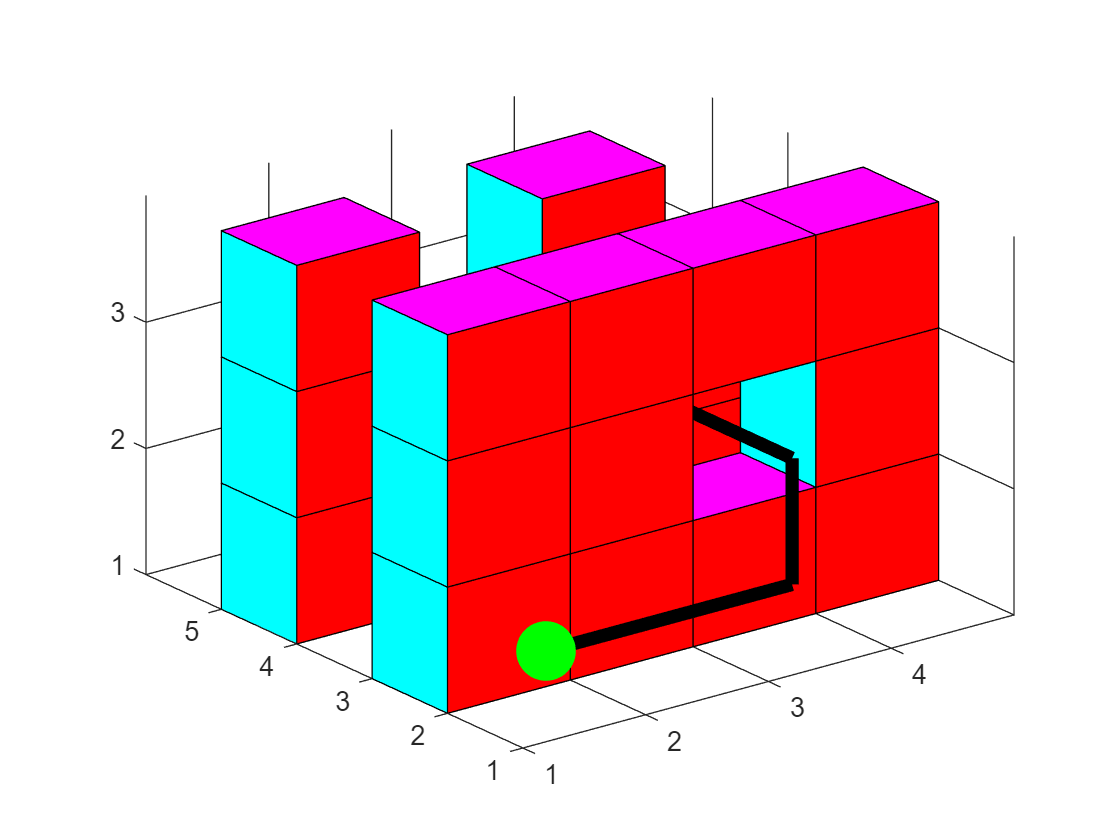

route = Astar3D_new(map, start, end_);
hold off

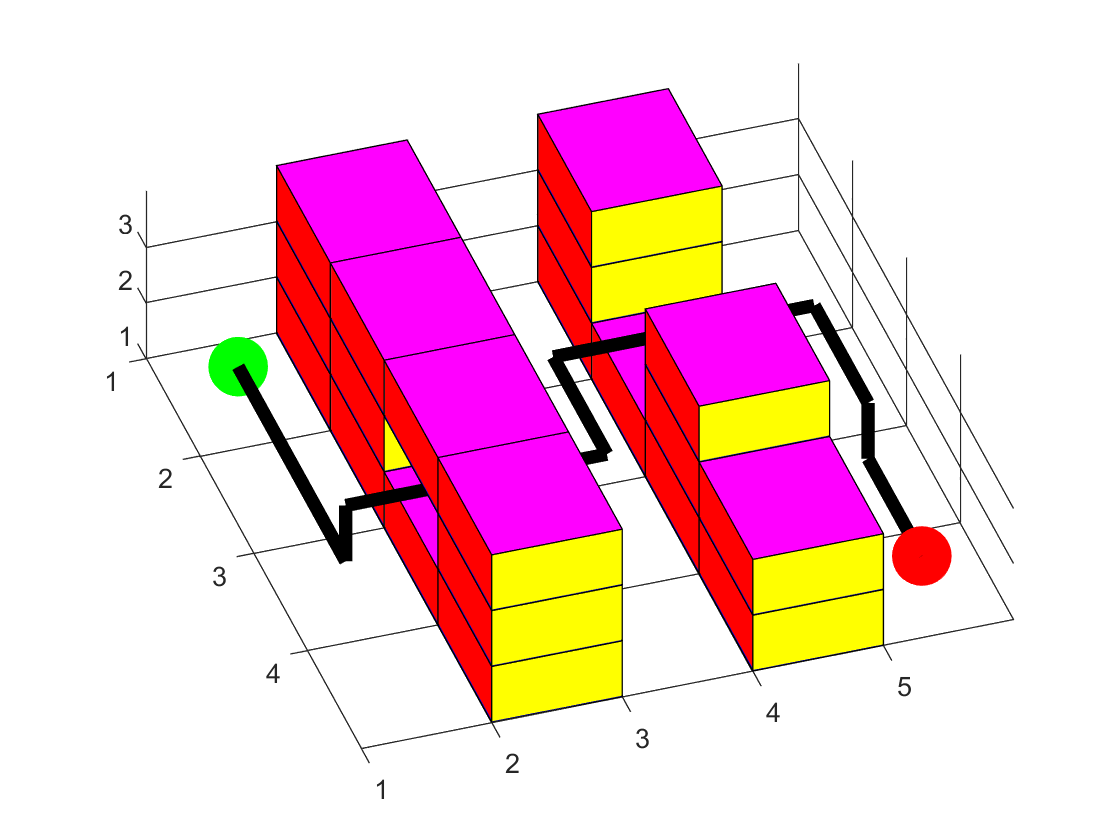

figure(1)
% Mark the start with green
scatter3(start(1)+0.5, start(2)+0.5, start(3)+0.5, ...
         500, [0,1,0],'filled')
hold on

% Mark the end with red
scatter3(end_(1)+0.5, end_(2)+0.5, end_(3)+0.5, ...
         500, [1,0,0], 'filled')
hold on

% Draw the obstacles
for i = 1:(length(wall) - 3)
    map = gen_square3d([wall(i, 1) wall(i, 1) + 1;...
                        wall(i, 2) wall(i, 2) + 1;...
                        wall(i, 3) wall(i, 3) + 1], map, 1);
    
end

% Set the axes
axis([1 max_x+1 1 max_y+1 1 max_z+1])
% Make the grid lines more visible
ax = gca;
ax.GridAlpha = 1.0;
grid on
set(gca, 'xtick', [0:1:max_x])
set(gca, 'ytick', [0:1:max_y])
set(gca, 'ztick', [0:1:max_z])
pause on;
for i = 2:length(route)
    plot3([route(i-1,1)+0.5,route(i,1)+0.5], ...
          [route(i-1,2)+0.5,route(i,2)+0.5], ...
          [route(i-1,3)+0.5,route(i,3)+0.5], ...
          'color',[0,0,0],'linewidth',5)
    hold on
    pause(0.1)
%     route(i,:)
end

% set(gcf,'Visible','on')